1.离散时间系统的响应

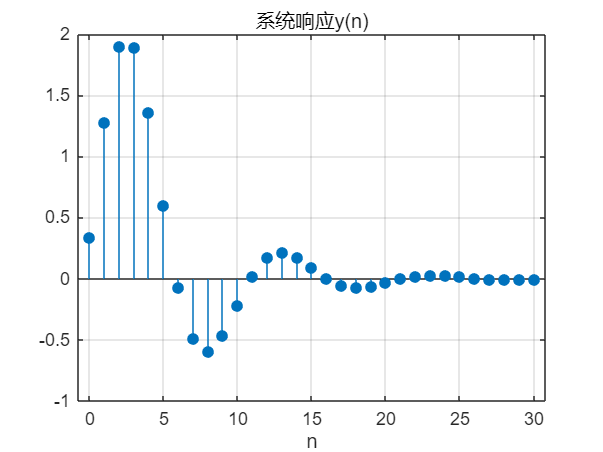

a = [3 -4 2];
b = [1 2];
n = 0:30;
x = (1/2).^n;
y = filter(b,a,x);
figure(1);
stem(n,y,'filled'),grid on
xlabel('n'),title('系统响应y(n)');

2.离散时间系统的单位取样响应

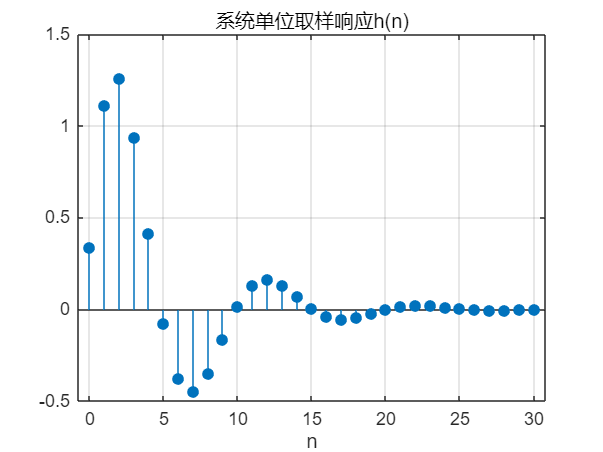

a = [3 -4 2];
b = [1 2];
n = 0:30;
x = (n==0);
h = filter(b,a,x);
figure(2);
stem(n,h,'filled'),grid on
xlabel('n'),title('系统单位取样响应h(n)')

3.使用impz(b,a,N)求单位取样响应的方法

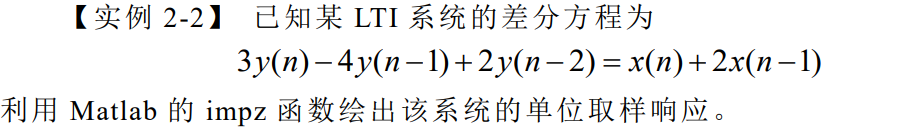

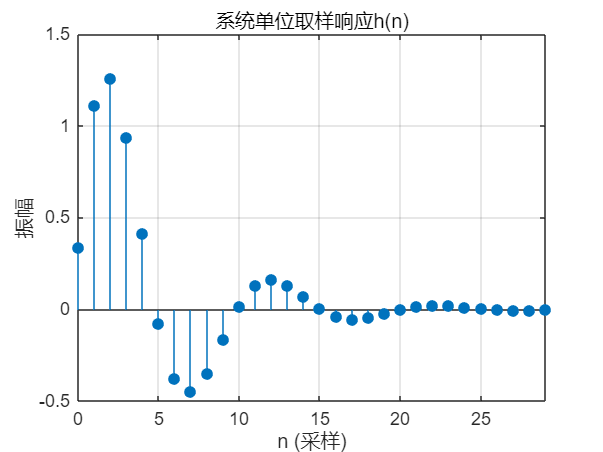

a = [3 -4 2];
b = [1 2];
impz(b,a,30); grid on;title('系统单位取样响应h(n)')

4.离散时间信号的卷积和运算

无法实现无限的累加

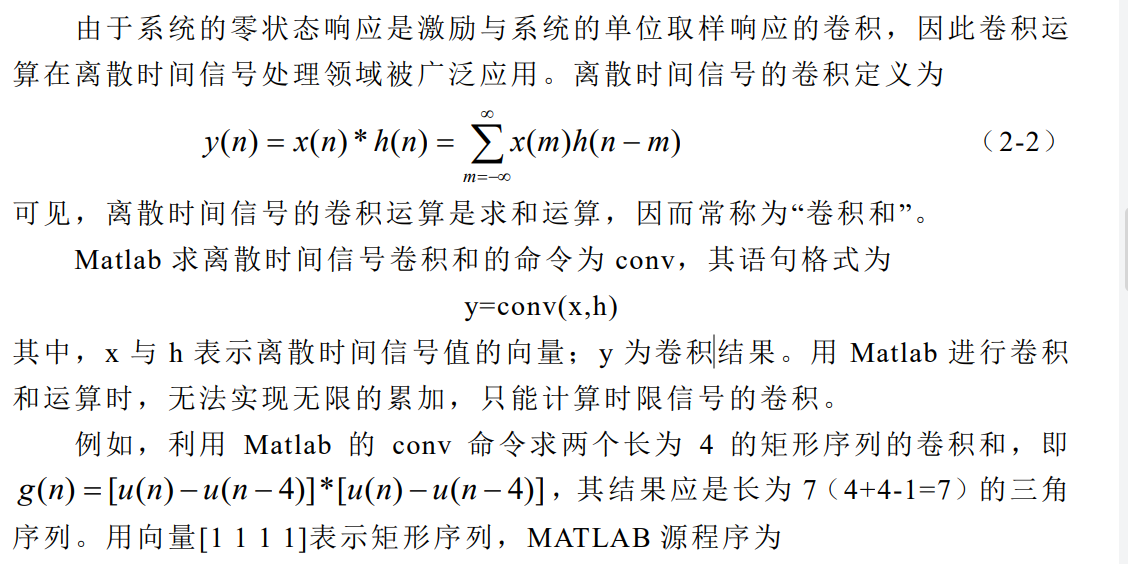

x1 = [1,1,1,1];
x2 = [1,1,1,1];
g = conv(x1,x2)

g =      1     2     3     4     3     2     1


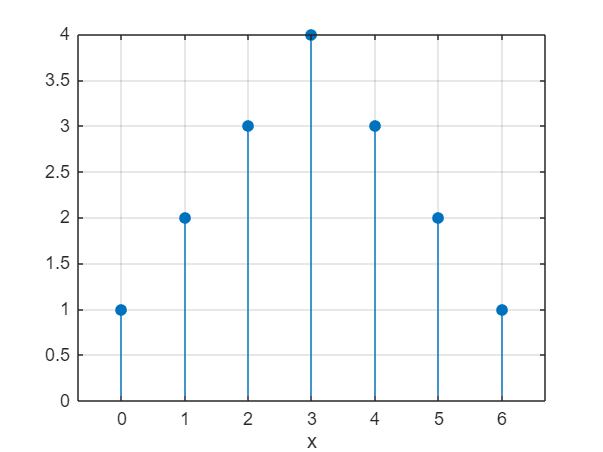

n = 0:6;
stem(n,g,'filled');grid on,xlabel('x')

两个时限序列的卷积和长度等于两个序列长度的和减1

5.求系统的零状态响应

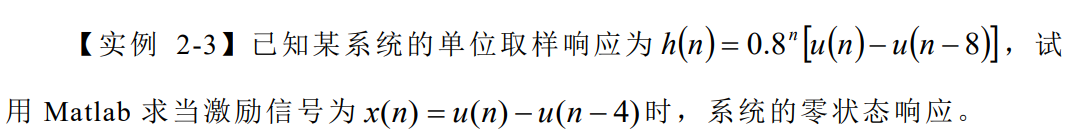

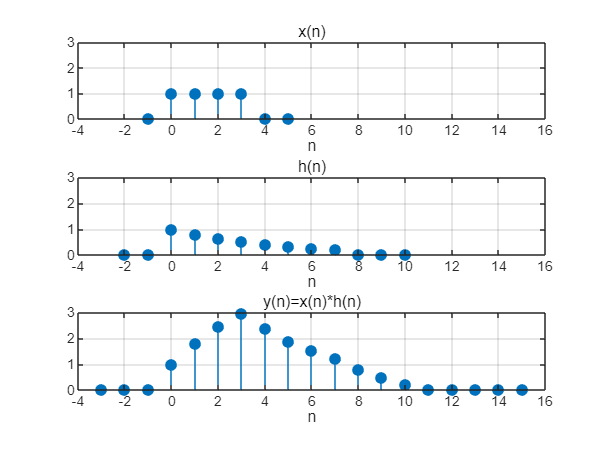

nx = -1:5;
nh = -2:10;
x = uDT(nx)-uDT(nx-4);
h = 0.8.^nh.*(uDT(nh)-uDT(nh-8));
y = conv(x,h);
ny1 = nx(1)+nh(1);   %卷积结果起始点
ny2 = nx(end)+nh(end); %卷积结果终点
ny = ny1:ny2;
subplot(311)
stem(nx,x,'fill'),grid on
xlabel('n'),title('x(n)')
axis([-4 16 0 3])


subplot(312)
stem(nh,h','filled'),grid on
xlabel('n'),title('h(n)')
axis([-4 16 0 3])


subplot(313)
stem(ny,y,'filled'),grid on
xlabel('n'),title('y(n)=x(n)*h(n)')
axis([-4 16 0 3])


function y=uDT(n)
    y = n>=0;
end

实验内容

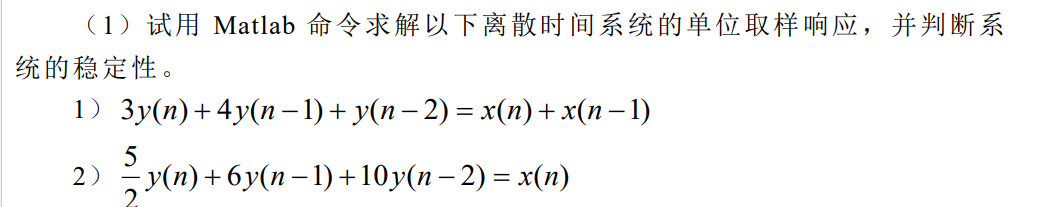

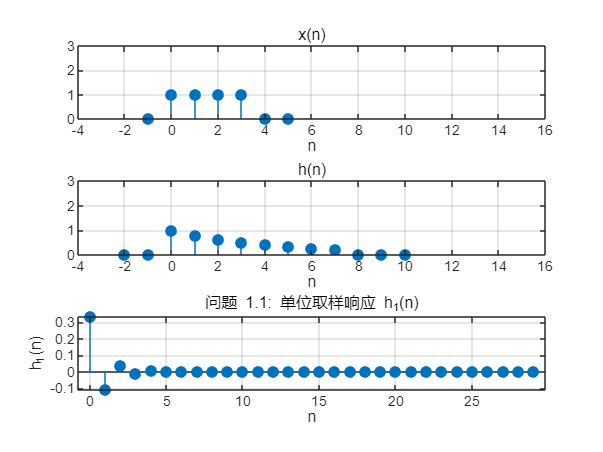

%1.1
a1 = [3, 4, 1]; % y(n) 的系数
b1 = [1, 1];   % x(n) 的系数
[h1, t1] = impz(b1, a1, 30); %MATLAB 中用于计算离散时间系统单位冲激响应 (impulse response) 的函数
stem(t1, h1, 'filled');
%h1:将是一个包含30个元素的向量，存储了冲激响应的值
%t1:将是一个包含30个元素的向量，存储了与 h1 对应的时间索引
title('问题 1.1: 单位取样响应 h_1(n)');
xlabel('n');
ylabel('h_1(n)');
grid on;

poles1 = roots(a1);
is_stable1 = all(abs(poles1) < 1);
fprintf('问题 1.1 的极点为: %f, %f\n', poles1(1), poles1(2));

问题 1.1 的极点为: -1.000000, -0.333333


if is_stable1
    fprintf('系统 1.1 稳定 (所有极点绝对值 < 1)。\n');
else
    fprintf('系统 1.1 不稳定 (存在极点绝对值 >= 1)。\n');
end

系统 1.1 不稳定 (存在极点绝对值 >= 1)。


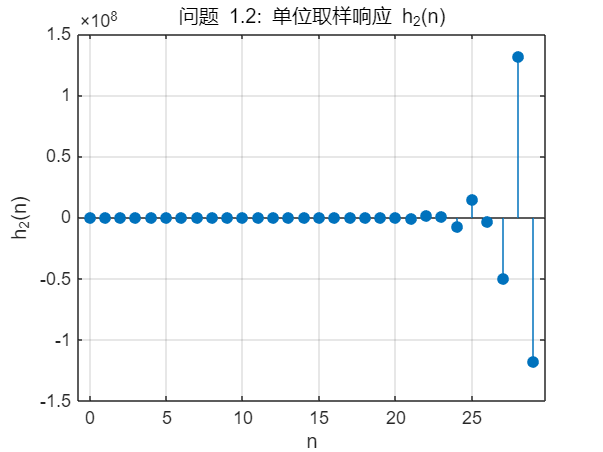

%1.2
a2 = [2.5, 6, 10]; % y(n) 的系数
b2 = [1];          % x(n) 的系数

% 计算冲激响应 (取前30个点)
[h2, t2] = impz(b2, a2, 30);

% 绘制冲激响应
figure;
stem(t2, h2, 'filled');
title('问题 1.2: 单位取样响应 h_2(n)');
xlabel('n');
ylabel('h_2(n)');
grid on;


% 判断稳定性
poles2 = roots(a2);
is_stable2 = all(abs(poles2) < 1);
fprintf('\n问题 1.2 的极点为: %f + %fi, %f + %fi\n', ...
        real(poles2(1)), imag(poles2(1)), real(poles2(2)), imag(poles2(2)));


问题 1.2 的极点为: -1.200000 + 1.600000i, -1.200000 + -1.600000i


fprintf('极点模长为: %f, %f\n', abs(poles2(1)), abs(poles2(2)));

极点模长为: 2.000000, 2.000000


if is_stable2
    fprintf('系统 1.2 稳定 (所有极点绝对值 < 1)。\n');
else
    fprintf('系统 1.2 不稳定 (存在极点绝对值 >= 1)。\n');
end

系统 1.2 不稳定 (存在极点绝对值 >= 1)。


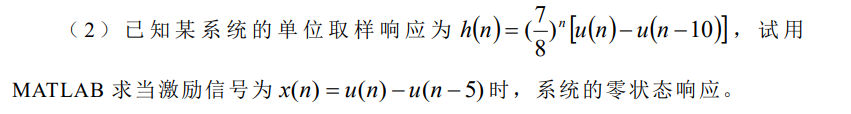

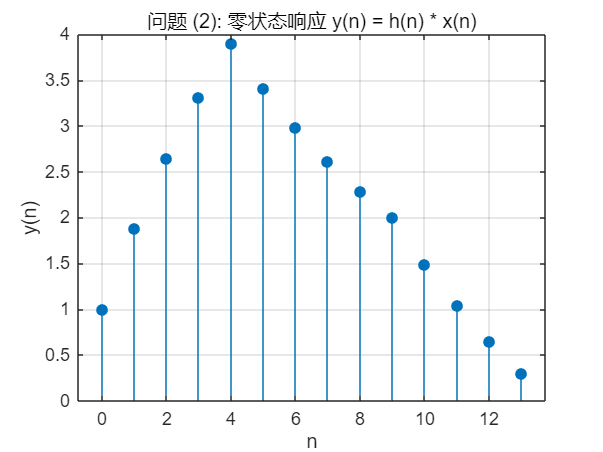

n_h = 0:9;
%hn的时间索引
h = (7/8).^n_h;
n_x = 0:4;
x = ones(1, length(n_x)); % [1, 1, 1, 1, 1]
% 零状态响应 y(n) = h(n) * x(n) (卷积)
y = conv(h, x);

% 计算 y(n) 对应的时间序列 n
% 卷积结果的长度为 length(h) + length(x) - 1
% 序列从 n=0 开始
n_y = 0:(length(y) - 1);

% 绘制零状态响应
figure;
stem(n_y, y, 'filled');
title('问题 (2): 零状态响应 y(n) = h(n) * x(n)');
xlabel('n');
ylabel('y(n)');
grid on;

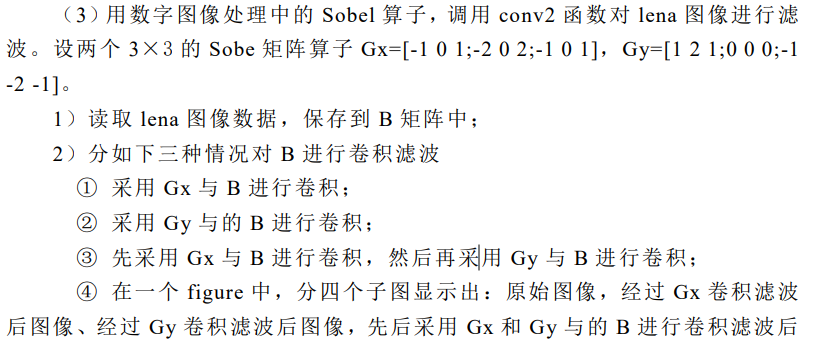

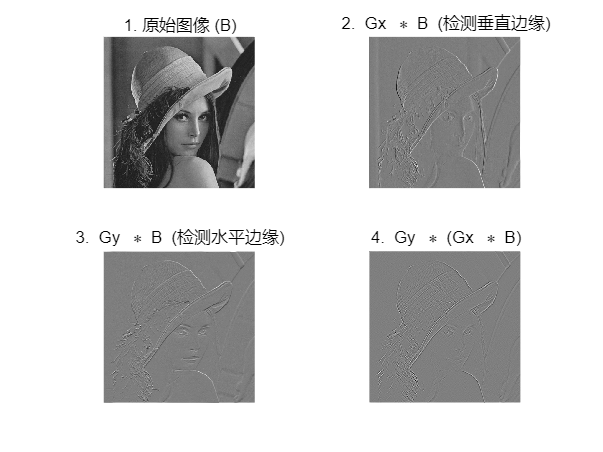

try
    I_rgb = imread('lena_colour.bmp');
catch
    fprintf('错误：无法读取图像。请确保图像文件在MATLAB路径中。\n');
    return;
end

% 转换为灰度图像
if size(I_rgb, 3) == 3
    I_gray = rgb2gray(I_rgb);
else
    I_gray = I_rgb;
end

% 转换为 double 类型以便进行卷积计算
B = im2double(I_gray);

% 定义 Sobel 算子
Gx = [-1 0 1; -2 0 2; -1 0 1];
Gy = [1 2 1; 0 0 0; -1 -2 -1];

% (3)-2: 分情况进行卷积滤波
% ① 采用 Gx 与 B 进行卷积
% 使用 'same' 选项使输出图像与输入图像 B 大小相同
I_Gx = conv2(B, Gx, 'same');

% ② 采用 Gy 与 B 进行卷积
I_Gy = conv2(B, Gy, 'same');

% ③ "先采用 Gx 与 B 进行卷积，然后再采用 Gy 与 B 进行卷积"
% 这部分题目描述即为分别执行 ① 和 ②，我们已在上面完成。

% ④ 在一个 figure 中，分四个子图显示
% (注意: 题目中第四个图 "先后采用 Gx 和 Gy 与 B 进行卷积后的图像" 
% 语义上最接近 "先用Gx卷，再用Gy卷其结果"，即 conv2(I_Gx, Gy, 'same')
% 另一种可能的理解是梯度幅值 sqrt(I_Gx.^2 + I_Gy.^2)，这也是标准的Sobel边缘检测)
% 这里我们按 "先后卷积" 的字面意思实现。

% 1. 原始图像
figure;
subplot(2, 2, 1);
imshow(B);
title('1. 原始图像 (B)');

% 2. 经过 Gx 卷积滤波后图像
% imshow(I_Gx, []) 会自动缩放显示范围，使黑白对比更明显
subplot(2, 2, 2);
imshow(I_Gx, []); 
title('2. Gx \ast B (检测垂直边缘)');

% 3. 经过 Gy 卷积滤波后图像
subplot(2, 2, 3);
imshow(I_Gy, []);
title('3. Gy \ast B (检测水平边缘)');

% 4. 先后采用 Gx 和 Gy 与 B 进行卷积 (即 Gy * (Gx * B))
I_Gx_Gy = conv2(I_Gx, Gy, 'same');
subplot(2, 2, 4);
imshow(I_Gx_Gy, []);
title('4. Gy \ast (Gx \ast B)');

思考题

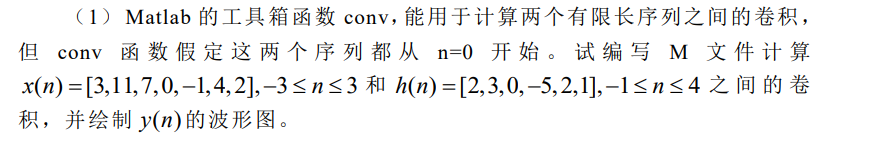

%% 清理工作区
clear;
clc;
close all;

%% 问题 (1): 计算任意起始点序列的卷积

fprintf('--- 问题 (1) ---\n');

--- 问题 (1) ---



% 1. 定义序列 x(n) 及其时间轴 nx
x = [3, 11, 7, 0, -1, 4, 2];
% n 的范围从 -3 到 3
nx = -3:3; 

% 2. 定义序列 h(n) 及其时间轴 nh
h = [2, 3, 0, -5, 2, 1];
% n 的范围从 -1 到 4
nh = -1:4;

% 3. 使用 conv 函数计算卷积
% MATLAB 的 conv 函数只计算序列的值，不关心 n 的起始点
y_values = conv(x, h);

% 4. 确定 y(n) 的时间轴 ny
% 卷积结果 y(n) 的起始点 = x(n)的起始点 + h(n)的起始点
ny_start = nx(1) + nh(1);

% 卷积结果 y(n) 的结束点 = x(n)的结束点 + h(n)的结束点
ny_end = nx(end) + nh(end);

% 创建 y(n) 的完整时间轴
ny = ny_start : ny_end;

% 打印结果到命令窗口
disp('y(n) 的序列值为:');

y(n) 的序列值为:


disp(y_values);

     6    31    47     6   -51    -5    41    18   -22    -3     8     2



fprintf('y(n) 的 n 轴范围为: %d 到 %d\n', ny(1), ny(end));

y(n) 的 n 轴范围为: -4 到 7


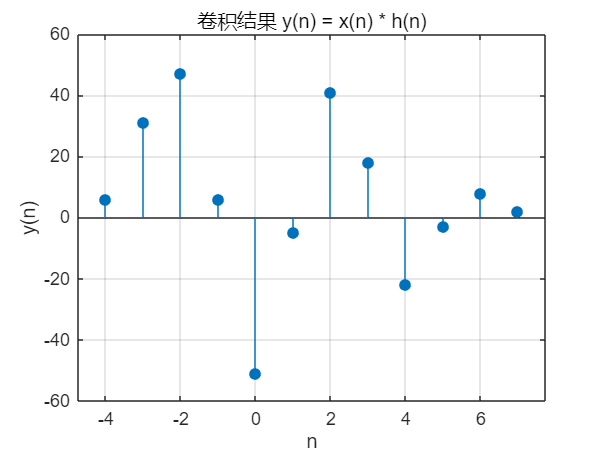


% 5. 绘制 y(n) 的波形图
figure;
stem(ny, y_values, 'filled');
title('卷积结果 y(n) = x(n) * h(n)');
xlabel('n');
ylabel('y(n)');
grid on;

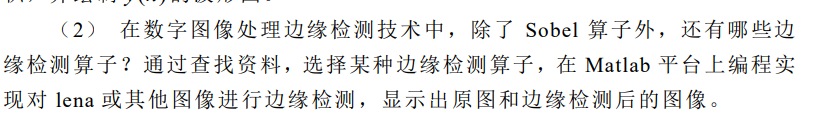

%% 问题 (2): Canny 边缘检测演示

fprintf('\n--- 问题 (2) ---\n');


--- 问题 (2) ---


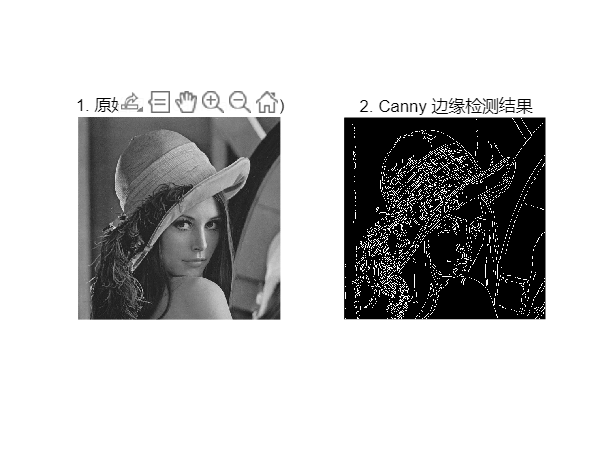


% 1. 读取图像
% 'lena' 图像不是 MATLAB 标准内置图像。
% 我们使用 MATLAB 内置的 'cameraman.tif' 图像作为示例。
% 如果您有 'lena.png' 文件，请将其放在工作目录并更改下一行。
try
    I_orig = imread('lena_colour.bmp');
catch
    fprintf('错误: 无法读取请检查图像处理工具箱是否安装。\n');
    return;
end

% 2. 确保图像为灰度图
if size(I_orig, 3) == 3
    I_gray = rgb2gray(I_orig);
else
    I_gray = I_orig;
end

% 3. 选择并实现 Canny 边缘检测
% 'edge' 函数是图像处理工具箱的一部分
% 'canny' 是所选的算法
BW_canny = edge(I_gray, 'canny');

% 4. 显示原图和边缘检测后的图像
figure;
subplot(1, 2, 1);
imshow(I_gray);
title('1. 原始图像 (cameraman.tif)');

subplot(1, 2, 2);
imshow(BW_canny);
title('2. Canny 边缘检测结果');